# Taller 15

### Péndulo simple con fuerza tangencial

### Juan Camilo Ospino M.

**CC: 1045743089**

### Introducción

Las ecuaciones diferenciales permiten modelar diferentes fenómenos transitorios, que cambian a lo largo del tiempo, por ejemplo. En esta entrega se propone una solución para definir el movimiento de un péndulo a lo largo del tiempo, entregando una serie de gráficas en donde se denota el comportamiento del péndulo cuando sus variables son alteradas.

### Punto 1.

Se pretende analizar una masa suspendida al extremo de un soporte, unida con una cuerda, para así oscilar con libertad. En el reposo, la masa figura estática gracias a la gravedad. Se emplea un modelo matemático a través de ecuaciones de estado donde se analiza la influencia de las variables existentes en ella.

Se denotan las variables $X_1$ y $X_2$ como variables, que significan la posición y velocidad angulares del sistema, dando lugar a las siguientes ecuaciones diferenciales:


$${\textrm{x₁}}^{\prime } =\textrm{x₂}$$
          
$${\textrm{x₂}}^{\prime } =-\frac{g}{l}\textrm{x₁}\;+\;\frac{f}{m}\textrm{x₂}\;+\;\frac{u}{m\;l}$$


Los parámetros de la ecuación son la masa, longitud, gravedad, fricción viscosa y fuerza externa, denotados $m,l,g,f,u$. La solución de estas ecuaciones diferenciales dan lugar a un gráfico expresando el comportamiento del péndulo a lo largo del tiempo.

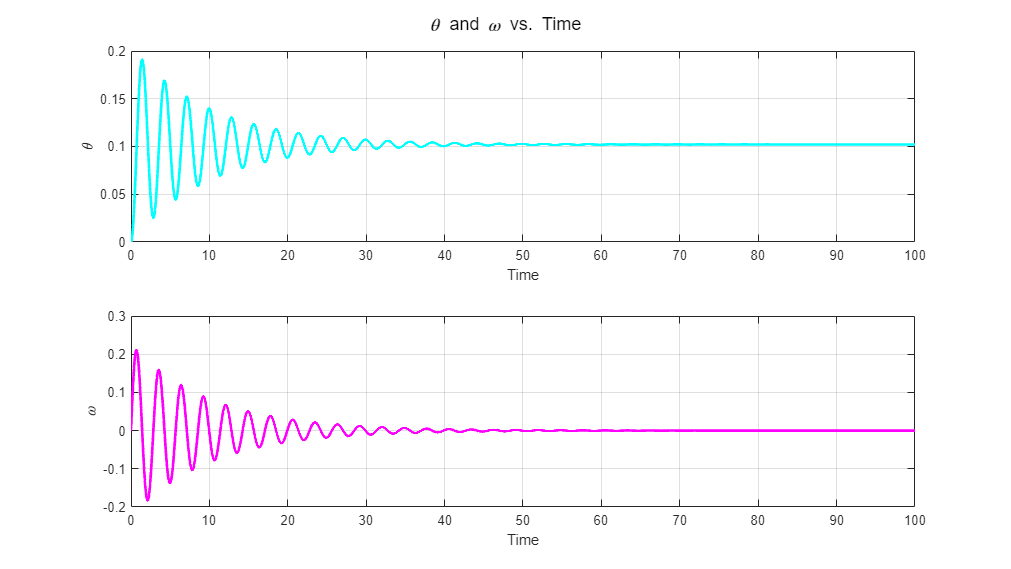

syms X1(t) X2(t)

%INIT

m = 1; 
g = 9.81; 
Theorical_Length = 2; 
f_values = 0.2; 
u = 1;

%Non linear second order State EQ

F1 = X2;
F2 = (-g/Theorical_Length)*sin(X1) - (f_values/m)*X2 + u/(m*Theorical_Length);
func = odeFunction([F1, F2], [X1, X2]);
IC = [0, 0]; %Stating Equilibrium

%Time

h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

%Solution

[Time, Sol] = ode45(func, tspan, IC);

% Extract Theta and Omega
Theta = Sol(:, 1);
Omega = Sol(:, 2);

% Plot Theta
figure;
subplot(2,1,1);
plot(Time, Theta, 'cyan', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('\theta');
%title('\theta vs. Time');

% Plot Omega
subplot(2,1,2);
plot(Time, Omega, 'magenta', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('\omega');
%title('\omega vs. Time');

% Adjust figure spacing and title
set(gcf, 'Position', get(0,'Screensize'));
sgtitle('\theta and \omega vs. Time');

Al ser descrito por el movimiento armónico simple, la posición y velocidad angular tienden a variar regularmente hasta que se estabiliza y vuelve a reposo, por lo que para encontrar un punto donde la fuerza externa suponga una inestabilidad marcada, se deberá notar el efecto del incremento de la fuerza, como se realiza a continuación:

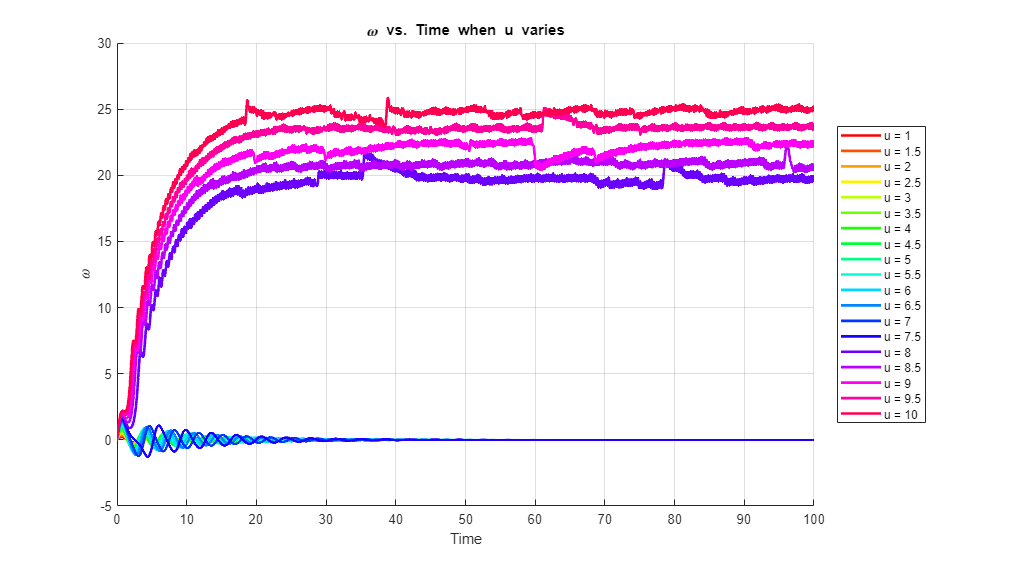

clf
syms X1(t) X2(t)

%INIT
m = 1; 
g = 9.81; 
Theorical_Length = 2; 
f_values = 0.2; 

%Time

h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

% Define a range of u values
u_values = 1:0.5:10; 

% Initialize an array to store results
friction_results = zeros(size(u_values));

% Define a color map for the lines
colors = hsv(length(u_values)); 

for i = 1:length(u_values)
    u = u_values(i);
    F1 = X2;
    F2 = (-g/Theorical_Length)*sin(X1) - (f_values/m)*X2 + u/(m*Theorical_Length);
    IC = [0, 0];
    func = odeFunction([F1, F2], [X1, X2]);
    [Time, Omega] = ode45(func, tspan, IC);

    % Store the Omega results
    friction_results(i) = Omega(end, 2);

    % Plot Omega for each u value
    hold on; 
    plot(Time, Omega(:, 2), 'LineWidth', 2, 'Color', colors(i, :));
end

% Add legend
legend_str = cellfun(@(x) ['u = ' num2str(x)], num2cell(u_values), 'UniformOutput', false);
legend(legend_str, 'Location', 'eastoutside');
grid on;
xlabel('Time');
ylabel('\omega');
title(['\omega vs. Time when u varies']);

Se observa que un cambio en la fuerza supone un tiempo mayor para lograr la estabilidad, en donde, al superar el valor de 7.5, se obtiene una perturbación que no logra ser contrarrestada por las otras fuerzas, por ende, inestable.

### Punto 2

Algunos modelos teóricos para sistemas físicos linealizan el comportamiento de los mismos con el propósito de simplificar los cálculos. En este punto se pretende estudiar la relación entre las variables que afectan al sistema en cuestión.

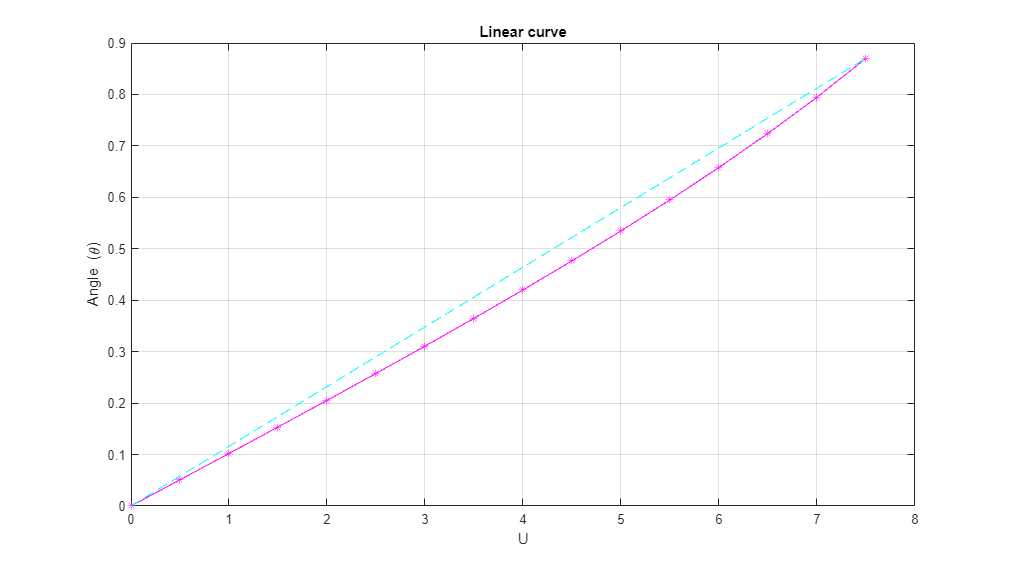

clf
syms X1(t) X2(t)

%INIT
m = 1; 
g = 9.81; 
Theorical_Length = 2; 
f_values = 0.2; 

%Time

h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

% Define a range of u values
u_values = 0:0.5:7.5; 

% Initialize an array to store results
Theta_results = zeros(size(u_values));

 

for i = 1:length(u_values)
    u = u_values(i);
    F1 = X2;
    F2 = (-g/Theorical_Length)*sin(X1) - (f_values/m)*X2 + u/(m*Theorical_Length);
    IC = [0, 0];
    func = odeFunction([F1, F2], [X1, X2]);
    [Time, State] = ode45(func, tspan, IC);

    % Store the Theta results
    Theta_results(i) = State(end, 1);
    
end

% Plot Theta for each u value
plot(u_values, Theta_results, 'magenta-*',[0 u_values(end)],[0 Theta_results(end)], 'cyan--');
grid on;
xlabel('U');
ylabel('Angle (\theta)');
title('Linear curve');

Para encontrar una relación con u, es necesario definirla dentro de su rango estable. En el gráfico se puede observar que la relación entre el desplazamiento angular y la fuerza externa poseen un comportamiento muy cercano al lineal dada la simplificación del modelo, que asume un movimiento armónico simple, que presenta una relación lineal entre sus variables. Es necesario notar esta relación entre variables dado lo idealizado que es el sistema y el fenómeno a estudiar, donde, por ejemplo, la fricción no juega un papel trascendental, aún cuando esta pueda tener efectos importantes en la vida real.

### Punto 3

Para este punto, se procura representar gráficamente la evolución del sistema en el espacio de fase, presentando una aproximación sobre el comportamiento del sistema

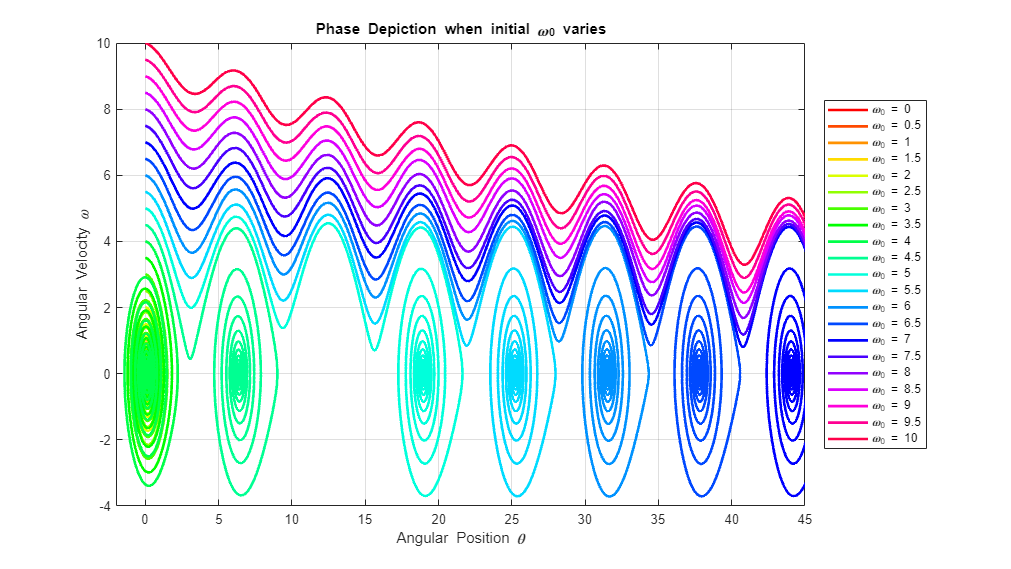

clf
syms X1(t) X2(t)

% INIT
m = 1; 
g = 9.81; 
Theorical_Length = 2; 
f_values = 0.2; 
u = 1; % Fix u at 1

% Time
h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

% Define a range of initial angular velocities
friction_values = 0:0.5:10; % Adjust as needed

% Initialize arrays to store results
friction_results = zeros(1, length(friction_values));

% Define a color map for the lines
colors = hsv(length(friction_values)); 

for i = 1:length(friction_values)
    theta_0 = friction_values(i);
    IC = [0, theta_0]; % Initial conditions with varying initial angular velocity
    
    F1 = X2;
    F2 = (-g/Theorical_Length)*sin(X1) - (f_values/m)*X2 + u/(m*Theorical_Length);
    func = odeFunction([F1, F2], [X1, X2]);
    [Time, State] = ode45(func, tspan, IC);


    % Plot theta and omega
    plot(State(:, 1), State(:, 2), 'LineWidth', 2, 'Color', colors(i, :));

    hold on;
    
end


% Plot specs
xlim([-2 45]);
xlabel('Angular Position \theta');
ylabel('Angular Velocity \omega');
legend_str = arrayfun(@(x) ['\omega_0 = ' num2str(x)], friction_values, 'UniformOutput', false);
legend(legend_str, 'Location', 'eastoutside');
title('Phase Depiction when initial \omega_0 varies');
grid on;

Con el retrato de fase, se logra observar qué valores en la velocidad angular inicial supondrían la rotación del péndulo. Se encuentra que con 4.5 rad/s daría una rotación, incrementando a medida que la velocidad angular inicial incrementa.

### Punto 4

Se busca analizar el péndulo cuando su posición angular inicial es alterada a través del retrato de fase.

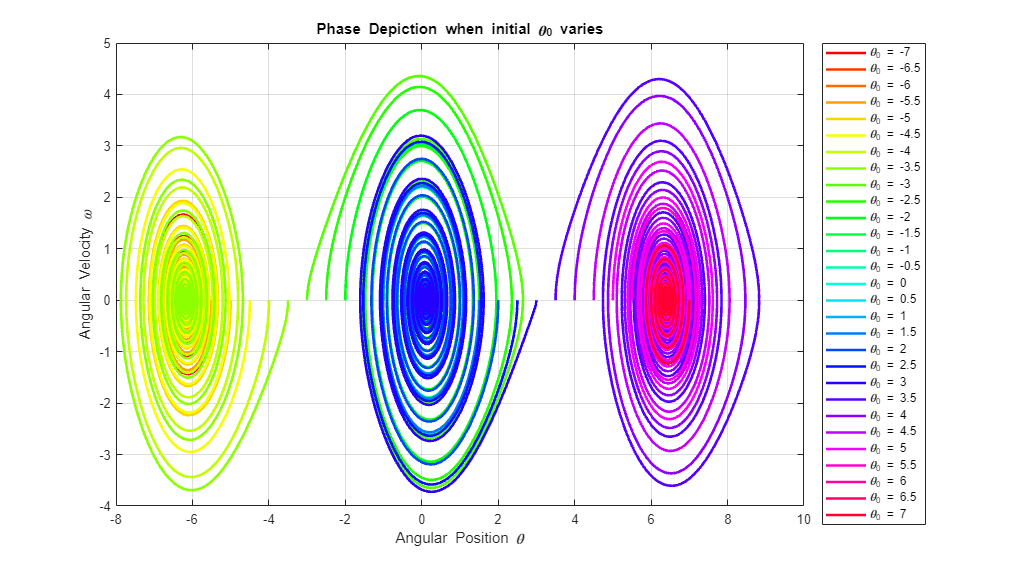

clf
syms X1(t) X2(t)

% INIT
m = 1; 
g = 9.81; 
Theorical_Length = 2; 
f_values = 0.2; 
u = 1; % Fix u at 1

% Time
h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

% Define a range of initial angular velocities
friction_values = -7:0.5:7; % Adjust as needed

% Initialize arrays to store results
friction_results = zeros(1, length(friction_values));

% Define a color map for the lines
colors = hsv(length(friction_values)); 

for i = 1:length(friction_values)
    theta_0 = friction_values(i);
    IC = [theta_0, 0]; % Initial conditions with varying initial angular velocity
    
    F1 = X2;
    F2 = (-g/Theorical_Length)*sin(X1) - (f_values/m)*X2 + u/(m*Theorical_Length);
    func = odeFunction([F1, F2], [X1, X2]);
    [Time, State] = ode45(func, tspan, IC);


    % Plot theta and omega
    plot(State(:, 1), State(:, 2), 'LineWidth', 2, 'Color', colors(i, :));

    hold on;
    
end


% Plot specs
xlabel('Angular Position \theta');
ylabel('Angular Velocity \omega');
legend_str = arrayfun(@(x) ['\theta_0 = ' num2str(x)], friction_values, 'UniformOutput', false);
legend(legend_str, 'Location', 'eastoutside');
title('Phase Depiction when initial \theta_0 varies');
grid on;

Se encuentran los puntos de equilibrio al rededor de [-6,0], el origen y [0, 6]. Por ende, cualquier valor inicial para $\theta_0$ que se ubique entre [-6,-3], [-3, 3] y [3, 6] encontraría el equilibrio en los puntos de equilibrio descritos previamente.

### Punto 5

En este caso, se pretende analizar el efecto de la longitud de la cuerda que soporta al péndulo.

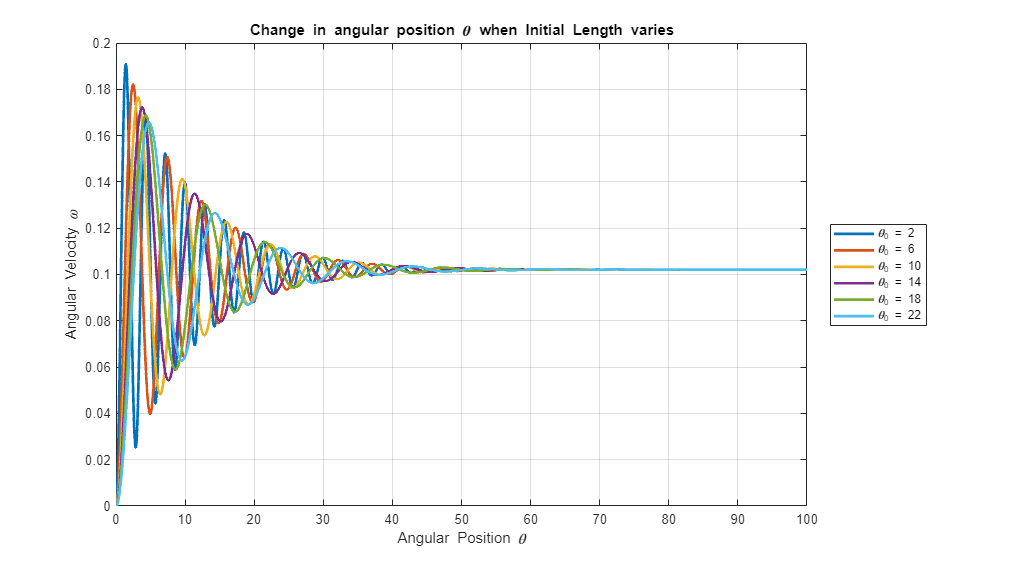

clf
syms X1(t) X2(t)

% INIT
m = 1; 
g = 9.81; 
f_values = 0.2; 
u = 1; 

% Time
h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

% Define a range of initial angular velocities
friction_values = 2:4:22; % Adjust as needed

% Initialize arrays to store results
friction_results = zeros(1, length(friction_values));

% Define a color map for the lines
colors = lines(length(friction_values)); 

for i = 1:length(friction_values)
    IC = [0, 0];     
    F1 = X2;
    F2 = (-g/friction_values(i))*sin(X1) - (f_values/m)*X2 + u/(m*friction_values(i));
    func = odeFunction([F1, F2], [X1, X2]);
    [Time, State] = ode45(func, tspan, IC);


    % Plot theta and omega
    plot(Time, State(:, 1), 'LineWidth', 2, 'Color', colors(i, :));
    hold on;
    
end

% Plot specs
xlim([0 100]);
xlabel('Angular Position \theta');
ylabel('Angular Velocity \omega');
legend_str = arrayfun(@(x) ['\theta_0 = ' num2str(x)], friction_values, 'UniformOutput', false);
legend(legend_str, 'Location', 'eastoutside');
title('Change in angular position \theta when Initial Length varies');
grid on;

La longitud del soporte supone una alteración en la frecuencia y periodo de las oscilaciones, de acuerdo con la fórmula matemática que define el periodo: $T=2\pi \sqrt{L\;/\;g}$ donde figura una relación directa entre la longitud y el periodo de oscilación.

Se encuentra que en la longitud máxima del gráfico, la frecuencia es menor y por ende, menos cantidad de osilaciones.

### Punto 6

En este punto, se pretende encontrar el efecto de la masa del péndulo en el sistema.

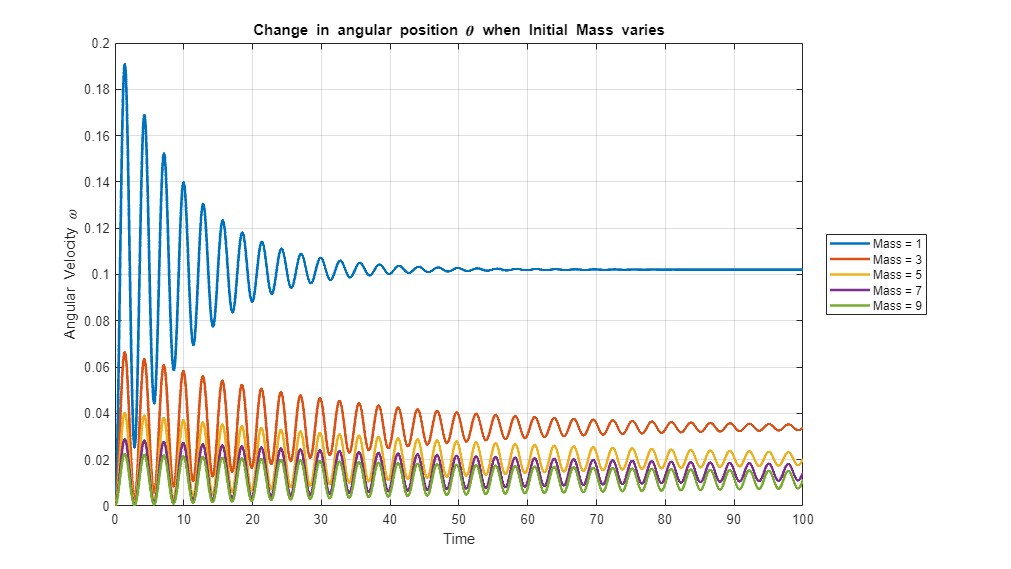

clf
syms X1(t) X2(t)

% INIT
Theorical_Length = 2; 
g = 9.81; 
f_values = 0.2; 
u = 1; 

% Time
h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

% Define a range of initial angular velocities
friction_values = 1:2:10; % Adjust as needed

% Initialize arrays to store results
friction_results = zeros(1, length(friction_values));

% Define a color map for the lines
colors = lines(length(friction_values)); 

for i = 1:length(friction_values)
    IC = [0, 0];     
    F1 = X2;
    F2 = (-g/Theorical_Length)*sin(X1) - (f_values/friction_values(i))*X2 + u/(friction_values(i)*Theorical_Length);
    func = odeFunction([F1, F2], [X1, X2]);
    [Time, State] = ode45(func, tspan, IC);


    % Plot theta and omega
    plot(Time, State(:, 1), 'LineWidth', 2, 'Color', colors(i, :));
    hold on;
    
end

% Plot specs
xlabel('Time');
ylabel('Angular Velocity \omega');
legend_str = arrayfun(@(x) ['Mass = ' num2str(x)], friction_values, 'UniformOutput', false);
legend(legend_str, 'Location', 'eastoutside');
title('Change in angular position \theta when Initial Mass varies');
grid on;

La amplitud de las oscilaciones, sin alterar la fuerza inicial aplicada en el sistema, se ve afectada por la masa del péndulo, encontrando una relación inversa. Se encuentra que una masa menor, al tener menor inercia, oscilaría con mayor diferencia entre puntos máximos y mínimos. En el gráfico, se puede ver que la velocidad angular a medida que la masa aumenta, se ve disminuida, y tiende a estabilizarse después de una masa menor, también debido a la inercia y a la fuerza de fricción.

### Punto 7

En este caso, se analizará el efecto de la fricción en el sistema.

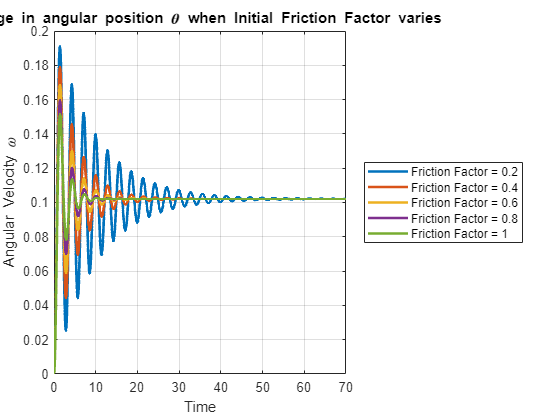

clf
syms X1(t) X2(t)

% INIT
Theorical_Length = 2; 
g = 9.81; 
m = 1; 
u = 1; 

% Time
h = 0.01;
tmax = 100;
tspan = 0:h:tmax; 

% Define a range of initial angular velocities
friction_values = 0.2:0.2:1; % Adjust as needed

% Initialize arrays to store results
friction_results = zeros(1, length(friction_values));

% Define a color map for the lines
colors = lines(length(friction_values)); 

for i = 1:length(friction_values)
    IC = [0, 0];     
    F1 = X2;
    F2 = (-g/Theorical_Length)*sin(X1) - (friction_values(i)/m)*X2 + u/(m*Theorical_Length);
    func = odeFunction([F1, F2], [X1, X2]);
    [Time, State] = ode45(func, tspan, IC);


    % Plot theta and omega
    plot(Time, State(:, 1), 'LineWidth', 2, 'Color', colors(i, :));
    hold on;
    
end

% Plot specs
xlim([0 70])
xlabel('Time');
ylabel('Angular Velocity \omega');
legend_str = arrayfun(@(x) ['Friction Factor = ' num2str(x)], friction_values, 'UniformOutput', false);
legend(legend_str, 'Location', 'eastoutside');
title('Change in angular position \theta when Initial Friction Factor varies');
grid on;

El efecto de la fricción se ve en la amplitud y en el tiempo necesario para encontrar la estabilidad. Para una masa constante, al aumentar el coeficiente de fricción, supone una oscilación más corta y un tiempo de estabilidad reducido, debido al efecto directo que tiene la fricción en la velocidad angular del péndulo.

### Punto 8

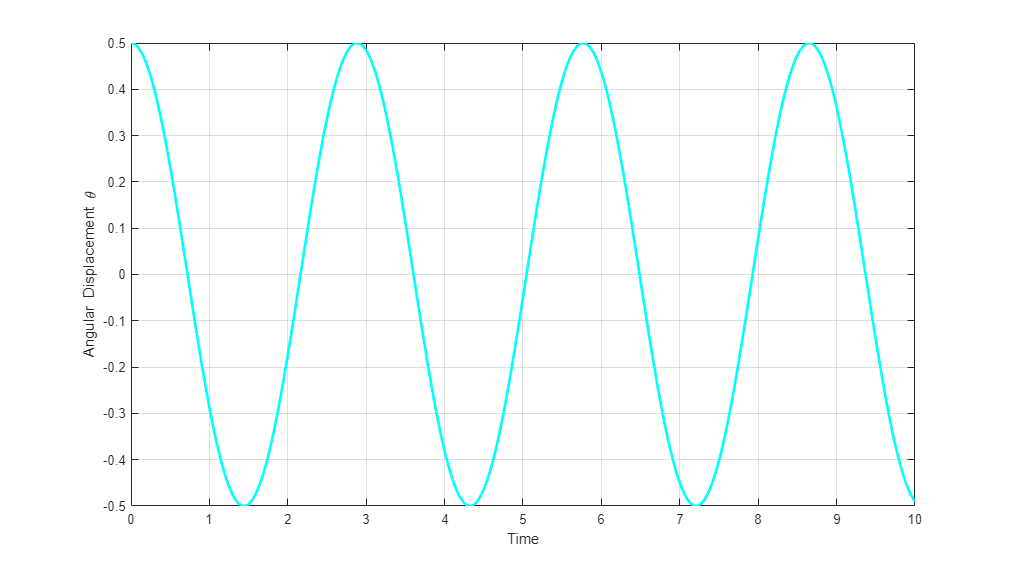

clf
syms X1(t) X2(t) 

%INIT
m = 1; 
g = 9.8; 
Theorical_Length = 2; 
f = 0; 
u = 0; 

%Function and initial condiiton
F1 = X2;
F2 = -(g/Theorical_Length)*sin(X1) - (f/m)*X2 + u/(m*Theorical_Length);
func = odeFunction([F1 F2],[X1 X2]);
IC = [0.5, 0]; %Stating Equilibrium

%Time constraint

h = 0.01;
tmax = 10;
tspan = 0:h:tmax; 

%Solution

[Time, Sol] = ode45(func, tspan, IC);

%Plot
plot(Time, Sol(:, 1), 'LineWidth', 2, 'Color', 'cyan');
xlabel('Time');
ylabel('Angular Displacement \theta');
grid on;


%Period calculation

[Peak, Peak_Index] = findpeaks(Sol(:, 1));
Periods = diff(Time(Peak_Index));
disp(['The average period is: ', num2str(mean(Periods))])

The average period is: 2.885


A partir de los parámetros iniciales, se busca encontrar el valor de la gravedad $\mathit{\mathbf{g}}$ al conocer la longitud de la cuerda del péndulo $\mathit{\mathbf{L}}$, teniendo en cuenta una ecuación que relacione ambos valores. Para esto se emplea la ecuación de Periodo $\mathit{\mathbf{T}}$ y de frecuencia angular $\omega$


$$T=\frac{2\pi }{\omega }$$
                  
$$\omega =\sqrt{\frac{g}{L}}$$


Llegando a la siguiente fórmula:


$$T=2\pi \sqrt{\frac{L}{g}}$$
 

Tal que el valor de la gravedad es una función de la longitud de la cuerda y el periodo, que pueden ser encontradas experimentalmente.

### Punto 9

En este punto se procura, a partir de datos experimentales, encontrar el valor del coeficiente de fricción y de la masa.

clf

syms X1(t) X2(t)

%Section to find optimized parameters

% Experimental Data
Time_Exp = 0:0.4:10;
Theta_Exp = [0 0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];

% U/S
options = optimset();

% Initial Mass and FF
params0 = [0.3, 0.5];

% Define function to find fit
model = @(params) simulate_pendulum(params, Time_Exp, Theta_Exp);

% Optimization
params_fit = fminsearch(model, params0, options);

% Optimized Parameters
m_optimized = params_fit(1);
f_optimized = params_fit(2);

% Display optimized parameters
disp(['Optimized Mass: ', num2str(m_optimized)]);

Optimized Mass: 0.51869


disp(['Optimized Friction Factor: ', num2str(f_optimized)]);

Optimized Friction Factor: 0.64695



% Execute Simulation
Time_Sim = linspace(0, 10, length(Time_Exp));
Theta_Sim = simulate_pendulum(params_fit, Time_Sim, Theta_Exp);

disp(['The Error between the experimental and simulation data is: ', num2str(simulate_pendulum(params_fit, Time_Exp, Theta_Exp)), ' %']);

The Error between the experimental and simulation data is: 1.3614 %


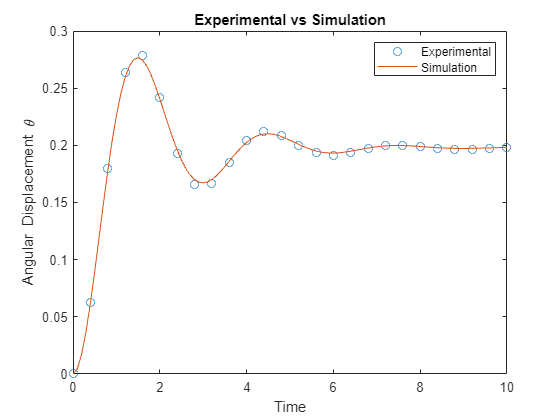




%INIT Parameters for ODE and Plot
g = 9.8; 
Theorical_Length = 2; 
u = 1;

%Parameters found previously
m = params_fit(1); 
f = params_fit(2);

F1 = X2;
F2 = -(g/Theorical_Length)*sin(X1) -(f/m)*X2 + u/(m*Theorical_Length);
func = odeFunction([F1 F2],[X1 X2]);

tspan = 0:0.1:10;

CI = [0 0];
[Time,Sol] = ode45(func,tspan,CI); 

theta = Sol(:,1); 
figure;
plot(Time_Exp,Theta_Exp,'o',Time,theta)
xlabel('Time')
ylabel('Angular Displacement \theta')
legend('Experimental', 'Simulation');
title('Experimental vs Simulation');

Se emplea un método de ajuste a través de Matlab, encontrando un valor para la masa de 0.51869 kg y un factor de fricción de 0.64695. El norma o error  de los datos de la simulación y los valores experimentales se encontró aproximadamente en 1.3614%.

### Punto 10

En el laboratorio, se empleó una masa de 0.52 kg y una longitud aproximada de 0.85 m de cuerda para el péndulo. A partir de esta información, se encuentra el largo aproximado a partir del video tomado en clase.

Theorical_Length = 0.85;
g = 9.81;
Osc_Time = 1.82;

Length = (Osc_Time^2*g)/(4*pi^2);

Error = ((Theorical_Length-Length)/Theorical_Length)*100;

disp(['The approximate length is: ', num2str(Length)])

The approximate length is: 0.8231


disp(['The average error is: ', num2str(Error), '%'])

The average error is: 3.1648%


A partir del video en clase donde se encontró un periodo de $1\ldotp 82$ segundos, y asumiendo el valor de la gravedad en $9\ldotp 81$ m/s² , se procede a encontrar el largo aproximado de la cuerda, obteniendo un resultado de 0.8231 y un error del 3.1648%.

Finalmente, no es posible relacionar los demás parámetros del sistema con la ecuación empleada anteriormente.

function error = simulate_pendulum(params, t, Theta_Exp)
    m = params(1);
    f = params(2);
    
    % Constants
    g = 9.81;
    l = 2;
    u = 1;
    
    % Define ODE
    f1 = @(t, X1, X2) X2;
    f2 = @(t, X1, X2) -(g/l)*sin(X1) - (f/m)*X2 + u/(m*l);
    
    % Solve ODE
    func = @(t, X) [f1(t, X(1), X(2)); f2(t, X(1), X(2))];
    [~, Theta] = ode45(func, t, [0; 0]);
    Theta = Theta(:, 1);
    
    % Calculate error
    error = norm(Theta - Theta_Exp);
end